# Demonstrate how combining multiple shorter exposures can simulate a single longer exposure.

There are some cases where a synthetic dataset with many different exposure times is valuable. However, especially with camera and object motion, each physically-based render can be computationally expensive.

So we've created a system that allows sequences of shorter exposures to be generated, alongside longer exposures. This both creates a dataset for us, and provides some metrics so that we can gauge wherer the simulated longer-exposure is sufficiently accurate.

First, we set up a default **scenario. **The ivScenario object (ISETVideo Scenario) sets default values for the scene, short exposure time, long exposure time, rays per pixel, and an optional flag to operate in an accelerated preview model (all of which can be over-ridden).

ieInit;
useScene = sceneMap("Stanford Bunny"); % Select desired scene
useScenario = ivScenario(useScene);

% ivScenario has defaults, but we can over-ride them
useScenario.exposureTime = 0.005;        % in seconds
useScenario.clipLength = 0.02;% Long Exposure
useScenario.raysPerPixel = 1024;
useScenario.fastPreview = 4;% divide rays & rez for previewing

% Save short exposure for later use
shortExposure = useScenario.exposureTime;
% calculate how many frames we need to add together
numFrames = round(useScenario.clipLength / useScenario.exposureTime);

#### Currently, the scene of the Stanford Bunny adds object motion to the test sceario:

% If we have the bunny, start to test object motion


We select either a GPU render (for performance when we have only camera motion, or a CPU render if we also have object motion:



% Need to find a good way to do persistence
% Persistent variables aren't allowed in script



#### Now we can modify settings or accept the default, and then create our video clips

sceneVideoClip(useScenario); % multi-capture

[INFO]: Read 2 materials and 0 textures.
[INFO]: Attribute processing: 
[INFO]: Identified 1 assets; parsed up to line 9

----- Summary of recipe: bunny

               index      material        positions (m)           sizes (m)     
               _____    ____________    __________________    __________________

    Bunny_O      4      {'BunnyMat'}    {'0.00 0.00 1.00'}    {'0.12 0.12 0.10'}

From [0.00, 0.000000, 0.000000] to [0.00, 0.000000, 1.000000] up [0.00, 1.000000, 0.000000]
Film diagonal not used for pinhole and human eye
Film diagonal not used for pinhole and human eye


Elapsed time is 2.324267 seconds.
[INFO]: Uploading data:
[INFO]: Sent 329 bytes  received 16 bytes  230.00 bytes/sec
[INFO]: Data uploaded successfully.
[INFO]: USE Docker: docker  --context remote-orange exec -it  pbrt-cpu-david14293 sh -c " pbrt  --outfile /home/david81/ISETRemoteRender/bunny/renderings/bunny.exr /home/david81/ISETRemoteRender/bunny/bunny.pbrt "
[INFO]: Rendered remotely in: 6.43 sec
[INFO]: Downloading data:
[INFO]: Sent 271 bytes  received 398 bytes  1,338.00 bytes/sec
[INFO]: Data downloaded successfully.
[INFO]: Output file:  renderings/bunny.exr
Elapsed time is 2.151256 seconds.
[INFO]: Uploading data:
[INFO]: Sent 1,476 bytes  received 10,969 bytes  24,890.00 bytes/sec
[INFO]: Data uploaded successfully.
[INFO]: USE Docker: docker  --context remote-orange exec -it  pbrt-cpu-david14293 sh -c " pbrt  --outfile /home/david81/ISETRemoteRender/bunny/renderings/bunny.exr /home/david81/ISETRemoteRender/bunny/bunny.pbrt "
[INFO]: Rendered remotely in: 5.97 sec
[INFO]:

#### Now we change our exposure time and re-generate the scene:

useScenario.exposureTime = useScenario.clipLength;
sceneVideoClip(useScenario);

[INFO]: Read 2 materials and 0 textures.
[INFO]: Attribute processing: 
[INFO]: Identified 1 assets; parsed up to line 9

----- Summary of recipe: bunny

               index      material        positions (m)           sizes (m)     
               _____    ____________    __________________    __________________

    Bunny_O      4      {'BunnyMat'}    {'0.00 0.00 1.00'}    {'0.12 0.12 0.10'}

From [0.00, 0.000000, 0.000000] to [0.00, 0.000000, 1.000000] up [0.00, 1.000000, 0.000000]
Film diagonal not used for pinhole and human eye
Film diagonal not used for pinhole and human eye


Elapsed time is 2.019642 seconds.
[INFO]: STARTED Docker successfully
[INFO]: Uploading data:
[INFO]: Sent 1,466 bytes  received 10,969 bytes  24,870.00 bytes/sec
[INFO]: Data uploaded successfully.
[INFO]: USE Docker: docker  --context remote-orange exec -it  pbrt-cpu-david16713 sh -c " pbrt  --outfile /home/david81/ISETRemoteRender/bunny/renderings/bunny.exr /home/david81/ISETRemoteRender/bunny/bunny.pbrt "
[INFO]: Rendered remotely in: 6.48 sec
[INFO]: Downloading data:
[INFO]: Sent 46 bytes  received 14,561 bytes  9,738.00 bytes/sec
[INFO]: Data downloaded successfully.
[INFO]: Output file:  renderings/bunny.exr
Local cpCam ran  in: 13.15 seconds of CPU time.
Total cpCam ran  in: 21.5861 total seconds.


By default, results are in ivDirGet('computed'), labeled with their exposure time in ms,  and the frame number in the multi-frame sequence.

#### We call sceneSynthesize both on the multiple exposures to sum them up,  and on the longer exposure(s) which we want to compare. 

We do this even for the case of a single longer exposure because it also does some baseline processing of the raw scene.

(Typically the "start" frame is 001, so we've currently hard-coded that.)

sceneSynthesize(fullfile(ivDirGet('computed'), ...
    sprintf('%s*-%03d.exr', useScene, round(shortExposure * 1000))),numFrames);
sceneSynthesize(fullfile(ivDirGet('computed'), ...
    sprintf('%s*-%03d.exr', useScene, round(useScenario.clipLength * 1000))),1);

#### Now we can compare the synthesized scene(s). By default we use a monochrome sensor, and evaluate voltages.

sceneHomeDir =  ivDirGet('computed');
% scene names have 3 codes:
% * exposureTime in ms
% * first frame in series (typically 001)
% * last frame in series (typically 001 or numFrames)
% NOTE: We denoise if fastPreview > 1

[sensorSingle, sensorMulti] = sceneCompare( ...
    fullfile(sceneHomeDir,sprintf('%s-%03d-%03d-%03d.mat',useScene, ...
        round(shortExposure*1000), 1, numFrames)), ...
    fullfile(sceneHomeDir, sprintf('%s-%03d-%03d-%03d.mat',useScene, ...
        round(useScenario.exposureTime*1000),1,1)), useScenario.exposureTime);

Denoised in: 4.881
Denoised in: 4.399


#### Show voltage comparison results as a mesh

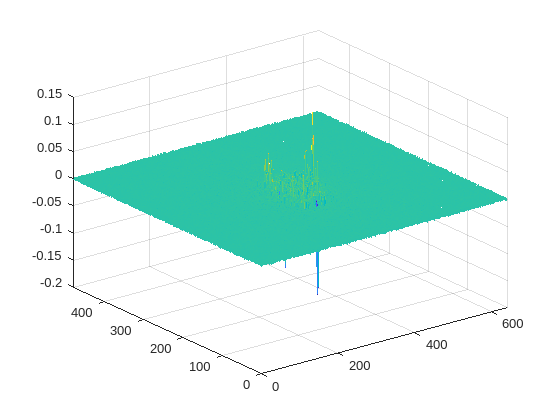

mesh(sensorSingle.data.volts - sensorMulti.data.volts);

#### Show SSIM for the multi-capture vs. single long capture:

[ssimVal, ssimMap] = ssim(sensorSingle.data.volts, sensorMulti.data.volts);
fprintf('%f\n',ssimVal)

0.995139


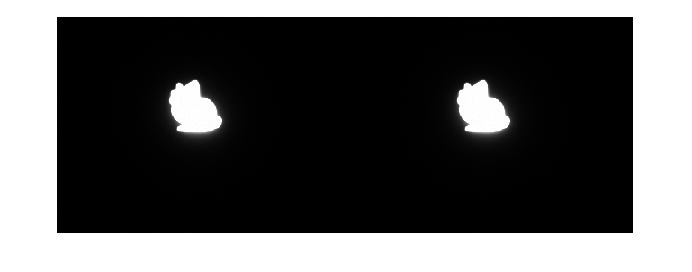

imshowpair(sensorSingle.data.volts,sensorMulti.data.volts,'montage');

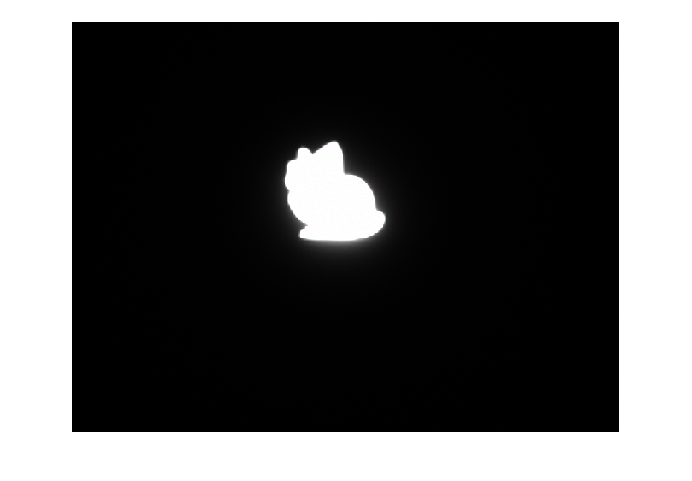

imshowpair(sensorSingle.data.volts,sensorMulti.data.volts,'falsecolor');

#### Use Histogram Equalization to dramatize any differences:

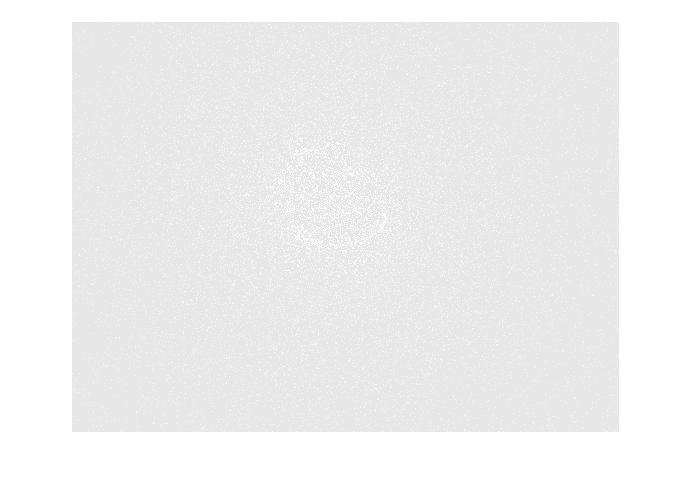

imshow(histeq(sensorSingle.data.volts - sensorMulti.data.volts));

function useScene = sceneMap(sceneLabel)
switch sceneLabel
    case 'Pavilion-Day'
        useScene = 'pavilion-day';
    case 'Pavilion Night'
        useScene = 'pavilion-night';
    case {"MacBeth Checker", 'Macbeth Checker'}
        useScene = 'MacBethChecker';
    case "Cornell Box"
        useScene = 'cornell_box';
    case 'Stanford Bunny'
        useScene = 'bunny';
end
end